% Rascunho
num = [1 1]; % numerador é 1*s^1 + 1*s^0
den = [1 0 0]; % denominador é 1*s^2 + 0*s + 0*s^0
g = tf(num,den) % estou supondo G como sendo a FT de MA

g =
 
  s + 1
  -----
   s^2
 
Continuous-time transfer function.



                % de um sistema com realimentação unitária

fprintf("Os pólos de G"); pole(g)

Os pólos de G

ans =      0
     0


fprintf("Os zeros de G"); zero(g)

Os zeros de G

ans = -1

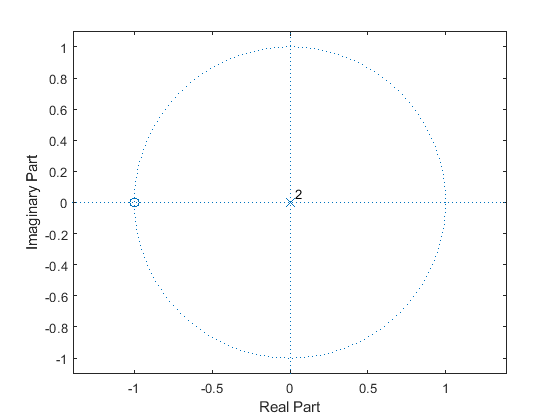

zplane(zero(g),pole(g)) % Vendo no plano

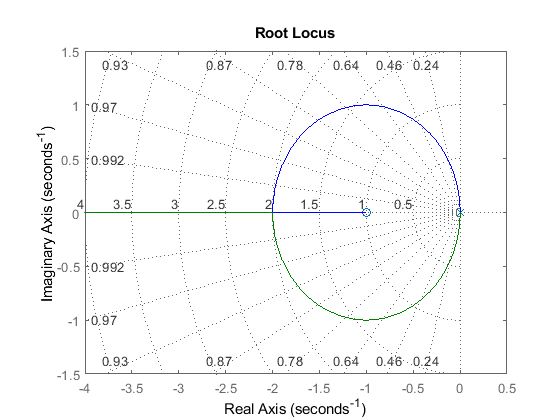

rlocus(g);grid; % Desenhando o LGR de G

% temos uma assíntota pois n_polos - n_zeros = 1

**Protagonista:**- Certas coisas eu só aceitei, como as de que o LGR começa saindo do zero e partindo para o pólo. Eu não entendi essa parada de ponto de partida e ponto de chegada. Posso estar falando besteira.

**Narrador:** Ele viu esse [vídeo](https://www.youtube.com/watch?v=eTVddYCeiKI&list=PLUMWjy5jgHK3-ca6GP6PL0AgcNGHqn33f&index=2) e entendeu. Se você escreve como P(s) + KQ(s) = 0, se K tende a zero, P(s) tende a ser normalmente os polos normais. Quando K tende ao infinito positivo, o P(s) tem que aparecer com uns valores muito maiores para poder cancelar o efeito de K, muitas vezes chegando aos valores dos zeros de Q(s), ou indo para o infinito (assíntota)

As regras (são 10, mas vou mostrar só 4):

- Existem n linhas (em que o n é o grau maior entre Q(s) ou P(s))

- Se k aumenta de 0 (início) para infinito (fim), o pólo tende a ir para o zeros

- Quando as raízes são complexas, elas sempre aparecem em pares conjugados

- Em momento algum o mesmo caminho de uma raiz vai cruzar a si mesmo. Mas caminhos de raizes diferentes podem se cruzar, não tem problema.

% Outra função g2 qualquer
num = [1 1];
den = [1 2 0];
g2 = tf(num, den) % FT DE MA com RU

g2 =
 
    s + 1
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



fprintf('zero'); zero(g2)

zero

ans = -1

fprintf('pole'); pole(g2)

pole

ans =      0
    -2


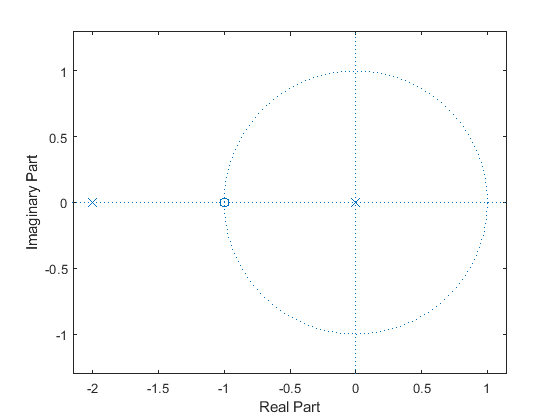

% temos uma assíntota pois n_polos - n_zeros = 1
zplane(zero(g2),pole(g2))

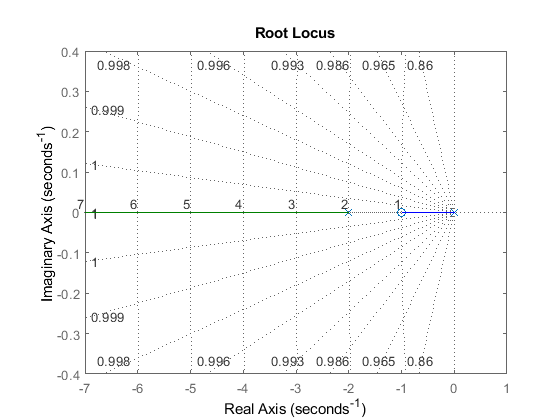

rlocus(g2);grid;

Tá, segundo o [vídeo](https://youtu.be/dOO5lyRzV8c?list=PLotZYHQBkGgQ7LzIkslTtXzmElRn7-Y99&t=1188), ele diz que o segmento depois do polo na origem não conta porque o número de componentes é par. Mas isso implica em que?

Se você tem um número par de componentes (seja ele polos ou zeros) à direita de um polo/zero, isso implica que não vai satisfazer o critério do somatório dos angulos (das retas traçadas do ponto de teste até os polos e zeros na reta real), pois:

Se for par, vai dar sempre 0, 360, 2k*180, ou seja, não pertence.

Se for impar, o somatório vai dar 180,540,-180.

-- Qualquer ponto que estiver na linha verde ou azul, vai te retornar um ganho K que vai te ajudar a ter um controle maior sobre a FTMF no final. Ou seja, se você achou um maldito ponto que pertença ao LGR e traçou, você obrigatoriamente consegue achar um valor de K que satisfaça aquelas condições.

Para o achar o K para o ponto s1 qualquer seu, você pode calcular de duas formas.

Uma é medindo o tamanho dos caminhos: 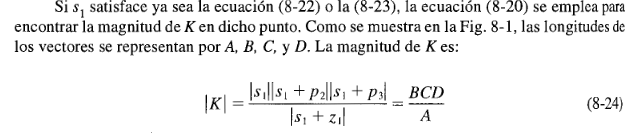

A outra forma é jogando o seu ponto s1 dentro da eq característica e achando o valor de k

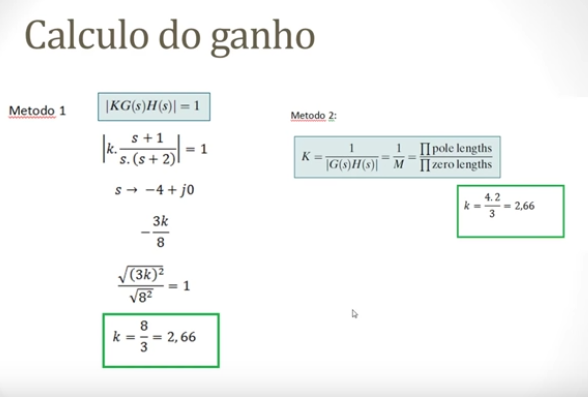

SABER LGR -> Controlar K -> Controlar FT

    5. A porção do eixo real que está a esquerda de um número ÍMPAR dos polos e dos zeros, fazem parte do LGR.

    6. As linhas entram e saem do eixo real sempre a 90º.

    7. Se tá sobrando polos, as linhas tendem ir ao infinito. Se tá sobrando zero, então a linha vem do infinito e chega nele.

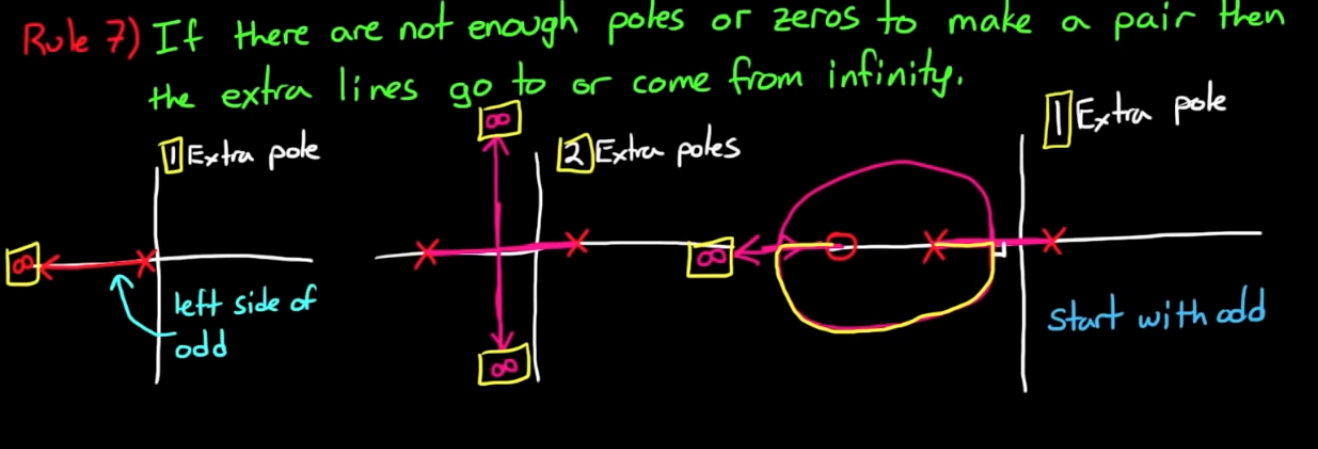

8. Os angulos das assintotas se dão pela fórmula de (2q+1)*180/(n-m). Você tem que achar o 'centroide' das assíntotas, caso tenha 2 ou mais polos ou zeros sem pares.

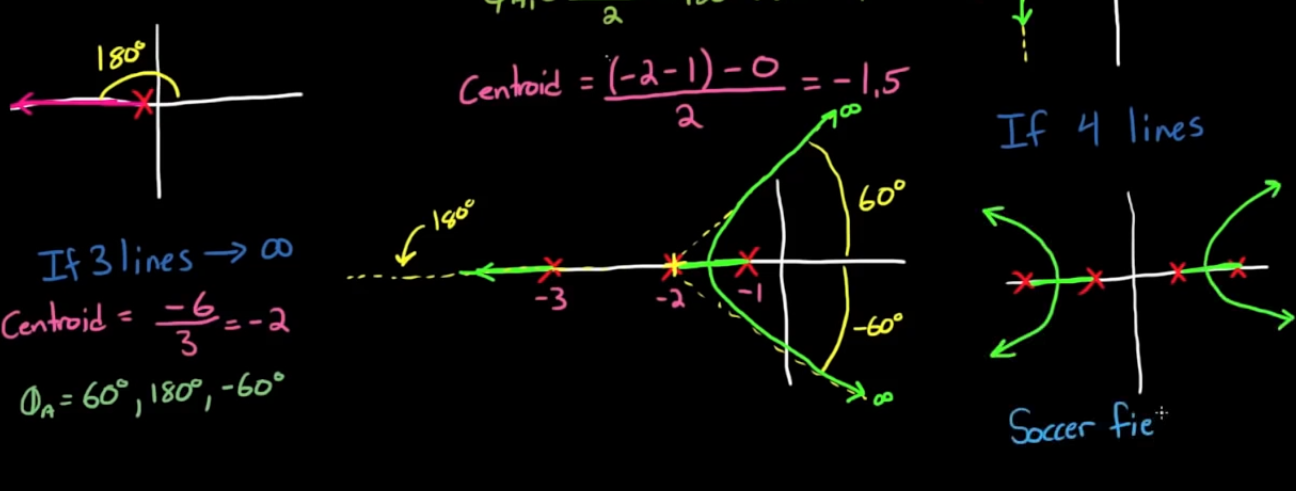

9. Se pelo menos duas linhas vão pro infinito, então a soma das raízes é constante (??) Talvez sirva para saber a melhor posição de K para não desastibilizar o sistema

10. O LGR para K indo de 0 para -inf, pode ser feito negativando s e adicionando 180º para os ângulos das assíntotas. Usualmente seu K costuma ser real positivo, então fique parcialmente despreocupado.

% sisotool() % Ferramenta para analise de SISO - vou ver mais tarde

# Desenhando um phase lead com LGR

'Phase lead' faz com que os polos do sistema sejam mais estáveis, pois os polos do compensador fazem os polos do sistemas tenderem para o lado esquerdo do plano S

** Pólo dominante é aquele mais perto da origem, em comparação com os que estão mais à esquerda dos eixos **

Diferença entre phase lead e phase lag.